隣接するchでの波形遅延は設定音速の違いによりどれくらい変動するのかを見積もる．焦点深度は最も深くして，もっとも顕著に遅延が認められる状況にした．

load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\kgrid.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\medium.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\param.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\sourse_wave.mat");
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\rfdata.mat");
load("H:/data/kwave/config/t_pos_2board.mat");
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx/2 - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
reference_point = zeros(1,num_echo_receiver);
reference_point_sec = zeros(1,num_echo_receiver);
distance_from_focal_point_all = zeros(1,num_echo_receiver);
num_echo_receiver = num_transmitter;
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
element_pitch = abs(t_pos(1,1) - t_pos(1,2));
mm = 1;
for ii = 9:num_depth
    focal_depth(1,ii) = single((ii+3)*kgrid.dx);
    focal_point(2,ii) = single(t_pos(2,1)-focal_depth(1,ii));
    focal_point(1,ii) = single((mm-1) * element_pitch);
end
ii = 9;kk = 1;
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
target_element = find((-focal_depth(1,ii)/2+focal_point(1,ii)<=...
    t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2+focal_point(1,ii))));
disp(target_element)

    49    50    51    52



for jj = 1:num_echo_receiver
    distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
    delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
    delay_time_all_sec = (distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk);%[sec]
    reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
    reference_point_sec(1,jj) = delay_time_all_sec(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))+(25-1)*kgrid.dt;
end

26ch・27ch間の遅延時間をもとめる

IMCL 1 %では

delay_26ch_to_27ch_measured = reference_point(1,26) - reference_point(1,27)

delay_26ch_to_27ch_measured = 13

delay_26ch_to_27ch_principle = reference_point_sec(1,26) - reference_point_sec(1,27)

delay_26ch_to_27ch_principle = 2.5142e-07

IMCL 20 %では

load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\kgrid.mat");
ii = 9;kk = 20;
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
target_element = find((-focal_depth(1,ii)/2+focal_point(1,ii)<=...
    t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2+focal_point(1,ii))));
disp(target_element)

    49    50    51    52



for jj = 1:num_echo_receiver
    distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
    delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
    delay_time_all_sec = (distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk);%[sec]
    reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
    reference_point_sec(1,jj) = delay_time_all_sec(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))+(25-1)*kgrid.dt;
end
delay_26ch_to_27ch2_measured = reference_point(1,26) - reference_point(1,27)

delay_26ch_to_27ch2_measured = 13

delay_26ch_to_27ch2_principle = reference_point_sec(1,26) - reference_point_sec(1,27)

delay_26ch_to_27ch2_principle = 2.5541e-07

現状のサンプリング周波数は

1/kgrid.dt/1e6

ans = 51.8000

- 焦点距離が最も大きい場合，駆動素子のうち端の素子と隣接する素子間でのRF信号の遅延時間が最も大きくなると思い込んで必要なサンプリングレートの概算をしていたが，その思い込みは間違っていた．

遅延時間を縦軸に，横軸に焦点深度をとるグラフを作成する．

IMCL 1.0 %の場合

load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\kgrid.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\medium.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\param.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\sourse_wave.mat");
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\rfdata.mat");
load("H:/data/kwave/config/t_pos_2board.mat");
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx/2 - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
reference_point = zeros(1,num_echo_receiver);
reference_point_sec = zeros(1,num_echo_receiver);
distance_from_focal_point_all = zeros(1,num_echo_receiver);
num_echo_receiver = num_transmitter;
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
element_pitch = abs(t_pos(1,1) - t_pos(1,2));
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
delay_measured_IMCL1 = zeros(1,num_depth);
delay_theory_IMCL1 = zeros(1,num_depth);
mm = 1;kk = 1;
v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
for ii = 9:num_depth
    focal_depth(1,ii) = single((ii+3)*kgrid.dx);
    focal_point(2,ii) = single(t_pos(2,1)-focal_depth(1,ii));
    focal_point(1,ii) = single((mm-1) * element_pitch);
end
for ii = 9:num_depth
    target_element = find((-focal_depth(1,ii)/2+focal_point(1,ii)<=...
    t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2+focal_point(1,ii))));
    for jj = 1:num_echo_receiver
        distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
        delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
        delay_time_all_sec = (distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk);%[sec]
        reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
        reference_point_sec(1,jj) = delay_time_all_sec(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))+(25-1)*kgrid.dt;
    end
    delay_measured_IMCL1(1,ii) = reference_point(1,target_element(1)) - reference_point(1,target_element(2));
    delay_theory_IMCL1(1,ii) = reference_point_sec(1,target_element(1)) - reference_point_sec(1,target_element(2));
end

IMCL 20.0 %の場合

load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\kgrid.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\medium.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\param.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\sourse_wave.mat");
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\rfdata.mat");
load("H:/data/kwave/config/t_pos_2board.mat");
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx/2 - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
reference_point = zeros(1,num_echo_receiver);
reference_point_sec = zeros(1,num_echo_receiver);
distance_from_focal_point_all = zeros(1,num_echo_receiver);
num_echo_receiver = num_transmitter;
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
element_pitch = abs(t_pos(1,1) - t_pos(1,2));
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
delay_measured_IMCL20 = zeros(1,num_depth);
delay_theory_IMCL20 = zeros(1,num_depth);
mm = 1;kk = 20;
v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
for ii = 9:num_depth
    focal_depth(1,ii) = single((ii+3)*kgrid.dx);
    focal_point(2,ii) = single(t_pos(2,1)-focal_depth(1,ii));
    focal_point(1,ii) = single((mm-1) * element_pitch);
end
for ii = 9:num_depth
    target_element = find((-focal_depth(1,ii)/2+focal_point(1,ii)<=...
    t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2+focal_point(1,ii))));
    for jj = 1:num_echo_receiver
        distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
        delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
        delay_time_all_sec = (distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk);%[sec]
        reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
        reference_point_sec(1,jj) = delay_time_all_sec(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))+(25-1)*kgrid.dt;
    end
    delay_measured_IMCL20(1,ii) = reference_point(1,target_element(1)) - reference_point(1,target_element(2));
    delay_theory_IMCL20(1,ii) = reference_point_sec(1,target_element(1)) - reference_point_sec(1,target_element(2));
end

図を作る．

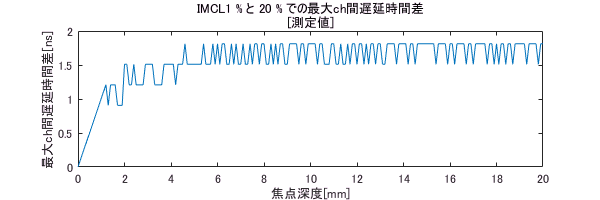

load("H:\result\2018_12_04_discuss_IMCL_limitation\matlab.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL1.0_pure\kgrid.mat")
kgrid1 = kgrid;
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\kgrid.mat")
kgrid20 = kgrid;
figure;
plot(focal_depth*1e3,(delay_measured_IMCL20*kgrid20.dt-delay_measured_IMCL1*kgrid1.dt)*1e9);
xlabel('焦点深度[mm]')
ylabel('最大ch間遅延時間差[ns]')
title({'IMCL1 % と 20 % での最大ch間遅延時間差';'[測定値]'})
savefig('H:\result\2018_12_04_discuss_IMCL_limitation\delay_measured_IMCL')
exportfig('H:\result\2018_12_04_discuss_IMCL_limitation\delay_measured_IMCL','png',[600 200]);

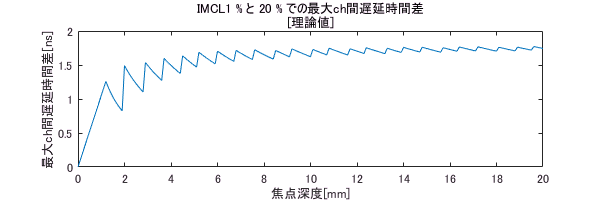

figure;
plot(focal_depth*1e3,(delay_theory_IMCL20-delay_theory_IMCL1)*1e9);
xlabel('焦点深度[mm]')
ylabel('最大ch間遅延時間差[ns]')
title({'IMCL1 % と 20 % での最大ch間遅延時間差';'[理論値]'})
savefig('H:\result\2018_12_04_discuss_IMCL_limitation\delay_theory_IMCL')
exportfig('H:\result\2018_12_04_discuss_IMCL_limitation\delay_theory_IMCL','png',[600 200]);